# File Manipulation and System Interaction

## Search Path

**Search path** is a subset of all folders on the fie system that MATLAB uses to efficiently locate files used with MathWorks products. All files in the folders on search path can be accessed by MATLAB.

**Order** of folders on search path is important:

When files in different folders (both in search path) with *same filename* exist, MATLAB uses the one in the folder *nearest the top* of the search path.

Search path includes:

- Folders provided with MATLAB and other MathWorks products

- MATLAB `userpath` (first on search path above folders supplied by MathWorks)  `S``earch Path Commands`

- `addpath:` Add folders to search path

- `rmpath:` Remove folders from search path

- `path:` View or change search path

- `savepath:` Save current search path

- `userpath:` View or change user portion of search path

- `genpath:` Generate path string

- `pathsep:` Search path separator for current platform

## Import/Export Data

Text File

- `importdata:` Load data from file

- `dlmread:` Read ASCII-delimited fie of numeric data into matrix

- `dlmwrite:` Write matrix to ASCII-delimited file

- `textscan:` Read formatted data from text fie or string

- `type:` Display contents of file Demo The **lift-drag** history for the flow around the **Ahmed body** The Ahmed body is a generic car body (a simplified vehicle model).

Plots taken from the post <https://www.comsol.com/blogs/studying-the-airflow-over-a-car-using-an-ahmed-body/ [https://www.comsol.com/blogs/studying-the-airflow-over-a-car-using-an-ahmed-body/](https://www.comsol.com/blogs/studying-the-airflow-over-a-car-using-an-ahmed-body/)> and <https://www.comsol.com/blogs/how-do-i-compute-lift-and-drag [https://www.comsol.com/blogs/how-do-i-compute-lift-and-drag/](https://www.comsol.com/blogs/how-do-i-compute-lift-and-drag/).>

`d``lmread`

`RESULT = dlmread(FILENAME)`

- Delimiter inferred from file format

`RESULT = dlmread(FILENAME,DELIMITER)`

- Delimiter specified by string `DELIMITER` (tabs are `'\t'`)

`RESULT = dlmread(FILENAME,DELIMITER,R,C)`

- `R, C` specify the row/column in file of upper left corner of data (zero-based)

`RESULT = dlmread(FILENAME,DELIMITER,RANGE)`

- `RANGE = [R1,C1,R2,C2]` specifies upper left and lower right corners of data (zero-based)

When a delimiter is inferred from the formatting of the file, *consecutive whitespaces* are treated as a single delimiter. By contrast, if a delimiter is specified by the DELIMITER input, any *repeated delimiter character* is treated as a separate delimiter. Demo

## Demo: import a lift/drag history (text folder OR single CSV)

LD_DIR = fullfile('data','liftdrag');

if isfolder(LD_DIR)
    dir(LD_DIR)
    fnames = dir(LD_DIR);
    fname = fullfile(LD_DIR, fnames(3).name);
    liftdrag = dlmread(fname,' ',1,0);
else
    % Fallback: a single CSV file (no header row)
    fname = 'liftdrag.csv';
    if ~isfile(fname)
        fname = fullfile('data','liftdrag.csv');
    end
    liftdrag = readmatrix(fname);
end


.                                    ..                                   unsteady.hdm.LiftDrag                unsteady.rom.0p995e.Off.LiftDrag     unsteady.rom.0p995e.Simple.LiftDrag  unsteady.rom.0p998e.Off.LiftDrag     unsteady.rom.0p998e.Simple.LiftDrag  



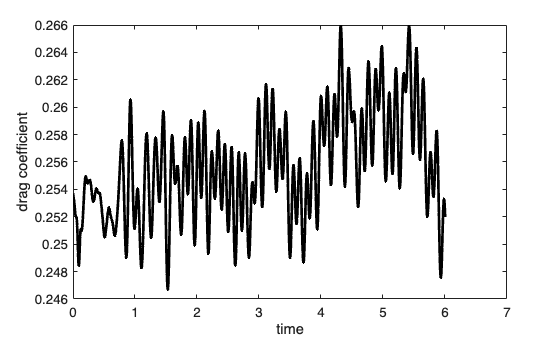

figure 
% plot the drag history (the 5th column vs. the 2nd column)
h(1)=plot(liftdrag(:,2),liftdrag(:,5),'k-','linew',2);
xlabel('time'); ylabel('drag coefficient');

`d``lmwrite`

`dlmwrite(FILENAME,M)`

- Write matrix `M` to file, delimited by `,`

- If `FILENAME` exists, it will be overwritten

`dlmwrite(FILENAME,M,DELIMITER)`

- Delimiter specified by string `DELIMITER` (tabs are `'\t'`)

`dlmwrite(FILENAME,M,DELIMITER,R,C)`

- `R,C` specify the row/column in file of upper left corner of data (zero-based)

Force `dlmwrite` to *append to existing file* by using the '􀀀|append|' flag

Additional attributes that given to `dlmwrite` that will alter the format of the ASCII file:

- `'delimiter', 'newline', 'roffset', 'coffset', 'precision'`

OUT_DIR = fullfile('outputs','lecture04_io');
if ~exist(OUT_DIR,'dir'), mkdir(OUT_DIR); end

dlmwrite(fullfile(OUT_DIR,'unsteady.liftdrag.copy.txt'), liftdrag, '\t')

The time history in each of the 5 files corresponds to a different method of solving the CFD problem.

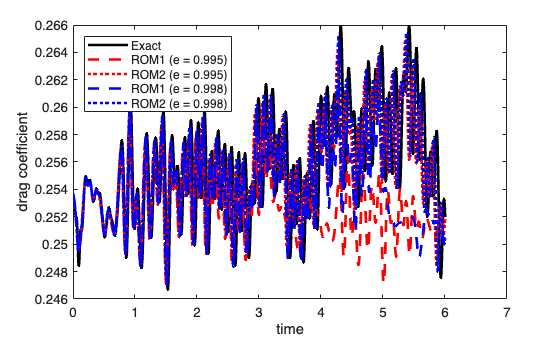

if isfolder(LD_DIR)
    pstr = {'r','b'};
    fnames = dir(LD_DIR);
    for i = 1:length(fnames)-2
        fname = fullfile(LD_DIR, fnames(i+2).name);
        liftdrag = dlmread(fname,' ',1,0);

        if i == 1
            figure();
            h(1)=plot(liftdrag(:,2),liftdrag(:,5),'k-','linew',2); hold on;
        elseif rem(i,2) == 0
            h(end+1)=plot(liftdrag(:,2),liftdrag(:,5),[pstr{floor(i/2)},'--'],'linew',2);
        else
            h(end+1)=plot(liftdrag(:,2),liftdrag(:,5),[pstr{floor(i/2)},':'],'linew',2);
        end
    end
    xlabel('time'); ylabel('drag coefficient');
    leg=legend('Exact','ROM1 (e = 0.995)','ROM2 (e = 0.995)','ROM1 (e = 0.998)','ROM2 (e = 0.998)');
    set(leg,'Location','northwest');
else
    % If you only have one dataset (e.g., liftdrag.csv), just plot it once.
    figure;
    plot(liftdrag(:,2), liftdrag(:,5), 'k-', 'linew', 2);
    xlabel('time'); ylabel('drag coefficient');
    legend('Example');
end

## Demo: Load a MAT-file scientific dataset (FNO 2D Navier–Stokes vorticity)

  Name              Size                     Bytes  Class     Attributes

  X_data           32x3x128x128            6291456  single              
  Y_data           32x4x128x128            8388608  single              
  mask            128x128                    65536  single              
  omega0           32x128x128              2097152  single              
  omega_pred       32x128x128              2097152  single              
  sample_idx        1x32                       128  int32               
  x                 1x128                      512  single              
  y                 1x128                      512  single              



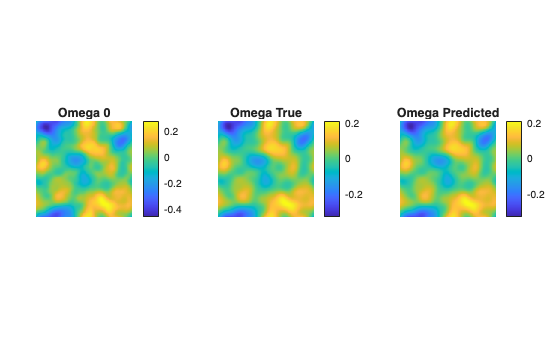

FNO_MAT = fullfile('data','ns2d_fno_pretrained_export.mat');
if ~isfile(FNO_MAT)
    FNO_MAT = 'ns2d_fno_pretrained_export.mat';
end

if isfile(FNO_MAT)
    whos('-file', FNO_MAT)
    S = load(FNO_MAT);

    % Visualize one sample: initial condition, ground truth, and prediction
    k = 1;
    omega0    = squeeze(S.X_data(k,1,:,:));
    omegaTrue = squeeze(S.Y_data(k,3,:,:));
    omegaPred = squeeze(S.omega_pred(k,:,:));

    figure;
    tiledlayout(1,3,'Padding','compact','TileSpacing','compact');
    nexttile; imagesc(omega0);    axis image off; title('Omega 0');        colorbar;
    nexttile; imagesc(omegaTrue); axis image off; title('Omega True');   colorbar;
    nexttile; imagesc(omegaPred); axis image off; title('Omega Predicted');   colorbar;
else
    warning("MAT file not found: %s", FNO_MAT);
end

- `fopen:` Open file

- `fclose:` Close one or all open files

- `feof:` Test for end of file

- `ferror:` Information about file IO errors

- `fgetl:` Read line from fie, remove newline character

- `fgets:` Read line from file, keep newline character

- `fileread:` Read contents of file into string

- `textscan:` Read formatted data from text file or string

- `fprintf:` Write data to text file

- `fread:` Read data from binary file

- `frewind:` Move file position indicator to beginning of open file

- `fscanf:` Read data from text file

- `fseek:` Move to specified position in file

- `ftell:` Position in open file

- `fwrite:` Write data to binary file

**Open/Close file**

`FID = fopen(FNAME)`

- Opens the file `FNAME`

- `FID` is a scalar integer valued double, called a **file identifier**

- Use `FID` as the first argument to other file IO routines

- If `fopen` cannot open the file, it returns `-1`

`FID = fopen(FNAME,PERMISSION)`

- Opens the file `FNAME` in the mode specified by `PERMISSION`

- open for reading (`r`), writing (`w`), appending (a) - create if file does not exist

- open for reading (`r+`), writing (`w+`), appending (`a+`) - do not create file

`ST = fclose(FID)`

- Closes the file associated with file identifier `FID`, obtained from `fopen`

- `fclose('all')` closes all open files except standard input, output, and error

**Read line from file**

`TLINE = fgetl(FID)`

- Returns the next line of a file associated with file identifier `FID` as a MATLAB string (identififier incremented)

- Line terminator is NOT included

`TLINE = fgets(FID)`

- Same as `fgetl` with line terminator included

% Choose a demo text file (original lift/drag text file if present; otherwise a generated report)
txtFile = fullfile('data','liftdrag','unsteady.hdm.LiftDrag');
if ~isfile(txtFile)
    % Fallback: generate a short text report from the FNO MAT-file
    OUT_DIR = fullfile('outputs','lecture04_io');
    if ~exist(OUT_DIR,'dir'), mkdir(OUT_DIR); end

    reportFile = fullfile(OUT_DIR, 'ns2d_report.txt');
    FNO_MAT = fullfile('data','ns2d_fno_pretrained_export.mat');
    if ~isfile(FNO_MAT)
        FNO_MAT = 'ns2d_fno_pretrained_export.mat';
    end

    if isfile(FNO_MAT)
        S = load(FNO_MAT);
        n = size(S.X_data,1);

        fidw = fopen(reportFile,'w');
        fprintf(fidw, 'ns2d_fno_pretrained_export.mat summary\n');
        fprintf(fidw, 'nSamples = %d\n', n);
        fprintf(fidw, 'X_data size = [%s]\n', num2str(size(S.X_data)));
        fprintf(fidw, 'Y_data size = [%s]\n', num2str(size(S.Y_data)));
        fclose(fidw);
        txtFile = reportFile;
    else
        warning("No text file and no MAT file found for fallback demo.");
        txtFile = reportFile;
        fidw = fopen(reportFile,'w'); fprintf(fidw, 'No demo data found.\n'); fclose(fidw);
    end
end

fid = fopen(txtFile);
line1 = fgetl(fid)

line1 = '#TimeIteration Time SubCycles NewtonSteps Lx Ly Lz '

for i = 1:10
%     line = fgetl(fid);
    line = fgets(fid); %try with fgets to see line spacing
    fprintf(line)
end

0 0.000000e+00 0 0 2.537068e-01 1.392221e+00 2.725644e-01 
1 4.795057e-03 1 6 2.535733e-01 1.392623e+00 2.715305e-01 
2 9.590094e-03 1 4 2.534343e-01 1.392893e+00 2.707774e-01 
3 1.438511e-02 1 4 2.532676e-01 1.393160e+00 2.700445e-01 
4 1.918010e-02 1 4 2.530754e-01 1.393440e+00 2.694729e-01 
5 2.397507e-02 1 4 2.528586e-01 1.393714e+00 2.691614e-01 
6 2.877003e-02 1 4 2.526241e-01 1.393962e+00 2.691134e-01 
7 3.356497e-02 1 4 2.523946e-01 1.394172e+00 2.693179e-01 
8 3.835989e-02 1 4 2.522040e-01 1.394339e+00 2.697696e-01 
9 4.315480e-02 1 4 2.520799e-01 1.394459e+00 2.704463e-01 


fclose(fid);

**Write to text file**

`fprintf(FID, FORMAT, A, ...)`

- Applies the `FORMAT` to all elements of array A and any additional array arguments in column order, and writes the data to a text file with file identifier  `FID` from `fopen`

- Set `FID` to 1 to print to the screen (or exclude)

year = 8/3;
fprintf('%f year at Stanford\n',year)

2.666667 year at Stanford


fprintf('%10.3f year at Stanford\n',year)

     2.667 year at Stanford


fprintf('%10.15f year at Stanford\n',year)

2.666666666666667 year at Stanford


Conversion Characters

- `%d,%i` Signed integer

- `%u` Unsigned integer

- `%f` Floating point, fixed notation

- `%e` Floating point, exponential notation (`e`)

- `%E` Same as `e` using E

- `%g` Compact form of `e`

- `%G` Compact form of E

- `%c` Single character

- `%s` String of characters

- `''` Single quote (')

- `%%` Percent sign (%)

- `\n` Newline

- `\t` Tab

v = 0.333;
fprintf('%f,\t%e, %E\n%g%% ''demo'' %G\n',v,v,v,v,v)

0.333000,	3.330000e-01, 3.330000E-01
0.333% 'demo' 0.333


- `ftell(FID)` returns the position in the file

- `fseek(FID,OFFSET,ORIGIN)` repositions the file position indicator to the byte with the specified `OFFSET` relative to `ORIGIN`

- `frewind(FID)` resets FID to the beginning of the file `FNAME`

- `feof(FID)` returns true if end-of-file indicator has been set

fid = fopen(txtFile);

fprintf('File location = %d\n',ftell(fid));

File location = 0


fprintf('At end of file? = %d\n',feof(fid));

At end of file? = 0


fseek(fid,0,'eof'); eofPos = ftell(fid);
fseek(fid, min(1000, eofPos), 'bof');
fprintf('File location = %d\n',ftell(fid));

File location = 1000


fprintf('At end of file? = %d\n',feof(fid));

At end of file? = 0


frewind(fid);
fprintf('File location = %d\n',ftell(fid));

File location = 0


fprintf('At end of file? = %d\n',feof(fid));

At end of file? = 0


fclose(fid);
% Quiz.
% What is the position of the end of the file? Write a few lines of code to 
% find this out. Consider using the |fgetl| function.

fid = fopen(txtFile);
while (fgetl(fid)~=-1); end
fprintf('File location = %d\n',ftell(fid));

File location = 76628


fprintf('At end of file? = %d\n',feof(fid));

At end of file? = 1


fclose(fid);

**Writing/reading binary files**

*Comparing to text files, binary files require less storage.*

`count = fwrite(FID,A)`

- Writes the elements of matrix A to the specified file

- The data are written in column order

- `count` is the number of elements successfully written.

`A = fread(FID)`

- Reads binary data from the specified file and writes it into matrix A

- Reads the entire file and positions the file pointer at the end of the file

`A = fread(FID,SIZE)`

- Reads the number of elements specified by `SIZE`

- Valid entries for `SIZE` are: `N` - read N elements into a column vector;  `inf` - read to the end of the file; `[M,N]` - read elements to fill an M-by-N matrix, in column order (N can be inf, but M can't)

`t``extscan`

Read *formatted* data from text file or string

`C = textscan(FID,'FORMAT',N)`

- Reads data from the file, using the `FORMAT` (recall conversion characters:  `%u, %i, %u, %f, %e, %E, %g, %G, %c, %s`) `N` times, wher|e N| is a positive integer

- To read additional data from the file after `N` cycles, call `textscan` again using the original `FID.`

- Useful when format of file not uniform through the end of the file.

**Demo: (surface) mesh data in the FRG format**

Data from UC Berkeley Computer Graphics group.

- First line of each file contains header information (number of nodes/elements, etc).

- Nodes contained in columns 2 - 4 for nodes file.

- Elements contained in columns 2 - 5 of elements file.

Extract node data into matrix p and element data into matrix t.

fname = fullfile('data','mesh_ex');
if ~isfile([fname,'.node']) && isfile('mesh_ex.node')
    fname = 'mesh_ex';
end

fid = fopen([fname,'.node']);
fgetl(fid)

ans = '7759  3  0  1'

nodes  = textscan(fid,'%d %f %f %f %d');
fclose(fid);
p = [nodes{2:end-1}];

fid = fopen([fname,'.ele']);
fgetl(fid)

ans = '32959  4  0'

elems  = textscan(fid,'%d %d %d %d %d');
fclose(fid);
t = [elems{2:end}];

Plot the mesh use the provided function `simpplot`:

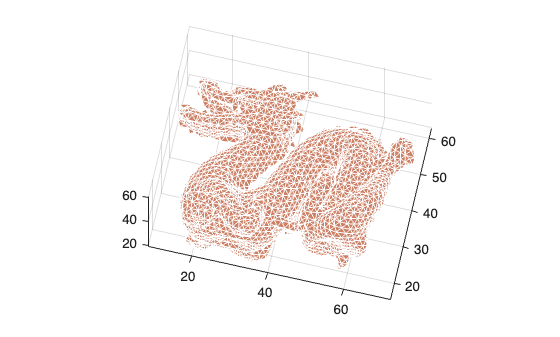

figure;
simpplot(p,t);
set(gca,'cameraposition',[40.5091 39.0167 488.426],...
        'view',[ 13,72]);

% Spreadsheets 
% Commands

- `xlsfinfo`: Determine if file contains Microsoft Excel spreadsheet

- `xlsread`: Read Microsoft Excel spreadsheet file

- `xlswrite`: Write Microsoft Excel spreadsheet file

`[STAT, MSG] = xlswrite(FNAME, M, SHEET, RANGE)`

- Writes the data in matrix `M` to the fie `FNAME` in the sheet specified by `SHEET` to the range of cells specified by `RANGE`

- `SHEET` can be numeric specifying worksheet index or quoted string

- `RANGE` is of the form '|X:Y|' where `X` indicates the upper left corner of the writable range and `Y` is the lower right corner (i.e. `'B2:D4'` is the 3-by-3 block of cells from row B to D and columns 2 to 4)

Requires ability to use Excel as COM server; otherwise, saves to CSV file.

OUT_DIR = fullfile('outputs','lecture04_io');
if ~exist(OUT_DIR,'dir'), mkdir(OUT_DIR); end

xlswrite(fullfile(OUT_DIR,'liftdrag.xls'), liftdrag)

Workaround: convert data to a table and use `writetable`

load and format the header

OUT_DIR = fullfile('outputs','lecture04_io');
if ~exist(OUT_DIR,'dir'), mkdir(OUT_DIR); end

% Workaround: convert data to a table and use |writetable|
% Load and format the header (supports either a text file in data/liftdrag/ or the provided liftdrag.xlsx/csv)

LD_DIR = fullfile('data','liftdrag');

if isfolder(LD_DIR)
    fnames = dir(LD_DIR);
    fname = fullfile(LD_DIR, fnames(3).name);
    liftdrag = dlmread(fname,' ',1,0);

    fid = fopen(fname);
    line1 = fgetl(fid);
    fclose(fid);

    header = split(line1);
    header(end)=[];
    header(1) = strip(header(1),'left','#');
    header = [{'No'}; header];
else
    xlsxFile = 'liftdrag.xlsx';
    if ~isfile(xlsxFile)
        xlsxFile = fullfile('data','liftdrag.xlsx');
    end

    if isfile(xlsxFile)
        raw = readcell(xlsxFile);
        header = string(raw(1,:)).';
        liftdrag = readmatrix(xlsxFile, "Range", "A2");
    else
        csvFile = 'liftdrag.csv';
        if ~isfile(csvFile)
            csvFile = fullfile('data','liftdrag.csv');
        end
        liftdrag = readmatrix(csvFile); % no header in this CSV
        header = ["No","TimeIteration","Time","SubCycles","NewtonSteps","Lx","Ly","Lz"].';
    end
end

T = array2table(liftdrag, 'VariableNames', cellstr(header(:).'));
liftXlsxOut = fullfile(OUT_DIR, 'liftdrag_from_table.xlsx');
writetable(T, liftXlsxOut)

% Choose an Excel file to read back in the next demo:
xlsFileForRead = fullfile('data','liftdrag.xlsx');
if ~isfile(xlsFileForRead)
    xlsFileForRead = liftXlsxOut;
end

## Demo: Write a compact metrics table from the FNO MAT-file (good use of Excel/CSV)

FNO_MAT = fullfile('data','ns2d_fno_pretrained_export.mat');
if ~isfile(FNO_MAT)
    FNO_MAT = 'ns2d_fno_pretrained_export.mat';
end

if isfile(FNO_MAT)
    S = load(FNO_MAT);
    n = size(S.X_data,1);

    rmse = zeros(n,1);
    maxabs = zeros(n,1);

    for k = 1:n
        ytrue = squeeze(S.Y_data(k,3,:,:));
        ypred = squeeze(S.omega_pred(k,:,:));
        d = ypred - ytrue;
        rmse(k) = sqrt(mean(d(:).^2));
        maxabs(k) = max(abs(d(:)));
    end

    TF = table(S.sample_idx(:), rmse, maxabs, ...
        'VariableNames', {'sample_idx','rmse','max_abs_err'});

    writetable(TF, fullfile(OUT_DIR, 'ns2d_pred_metrics.csv'));
    writetable(TF, fullfile(OUT_DIR, 'ns2d_pred_metrics.xlsx'));
end

`[NUM,TXT,RAW]=xlsread(FILE,SHEET,RANGE)`

- Reads the data specified in `RANGE` from the worksheet `SHEET`, in the Excel file specified in `FILE`.

- The full functionality of `xlsread` depends on the ability to start Excel as a COM server from MATLAB.

`[NUM,TXT,RAW]=xlsread(FILE,SHEET,RANGE,'basic')`

- Uses basic input mode. This is the mode used on UNIX platforms as well as on Windows when Excel is not available as a COM server.

- In this mode, xlsread does not use Excel as a COM server, which limits import ability.

- Without Excel as a COM server, `RANGE` will be ignored and, consequently, the whole active range of a sheet will be imported.

- Also, in basic mode, `SHEET` is case-sensitive and must be a string.

[NUM,TXT,RAW]=xlsread(xlsFileForRead)

NUM = 1.0e+03 *

         0         0         0         0    0.0003    0.0014    0.0003         0
    0.0010    0.0000    0.0010    0.0060    0.0003    0.0014    0.0003         0
    0.0020    0.0000    0.0010    0.0040    0.0003    0.0014    0.0003         0
    0.0030    0.0000    0.0010    0.0040    0.0003    0.0014    0.0003         0
    0.0040    0.0000    0.0010    0.0040    0.0003    0.0014    0.0003         0
    0.0050    0.0000    0.0010    0.0040    0.0003    0.0014    0.0003         0
    0.0060    0.0000    0.0010    0.0040    0.0003    0.0014    0.0003         0
    0.0070    0.0000    0.0010    0.0040    0.0003    0.0014    0.0003         0
    0.0080    0.0000    0.0010    0.0040    0.0003    0.0014    0.0003         0
    0.0090    0.0000    0.0010    0.0040    0.0003    0.0014    0.0003         0
    0.0100    0.0000    0.0010    0.0040    0.0003    0.0014    0.0003         0
    0.0110    0.0001    0.0010    0.0040    0.0003    0.0014    0.0003         0
    0.0120 

TXT = 1×8 cell array
    {'No'}    {'TimeIteration'}    {'Time'}    {'SubCycles'}    {'NewtonSteps'}    {'Lx'}    {'Ly'}    {'Lz'}


RAW = 1254×8 cell array
    {'No'}    {'TimeIteration'}    {'Time'}    {'SubCycles'}    {'NewtonSteps'}    {'Lx'    }    {'Ly'    }    {'Lz'}
    {[ 0]}    {[            0]}    {[   0]}    {[        0]}    {[     0.2537]}    {[1.3922]}    {[0.2726]}    {[ 0]}
    {[ 1]}    {[       0.0048]}    {[   1]}    {[        6]}    {[     0.2536]}    {[1.3926]}    {[0.2715]}    {[ 0]}
    {[ 2]}    {[       0.0096]}    {[   1]}    {[        4]}    {[     0.2534]}    {[1.3929]}    {[0.2708]}    {[ 0]}
    {[ 3]}    {[       0.0144]}    {[   1]}    {[        4]}    {[     0.2533]}    {[1.3932]}    {[0.2700]}    {[ 0]}
    {[ 4]}    {[       0.0192]}    {[   1]}    {[        4]}    {[     0.2531]}    {[1.3934]}    {[0.2695]}    {[ 0]}
    {[ 5]}    {[       0.0240]}    {[   1]}    {[        4]}    {[     0.2529]}    {[1.3937]}    {[0.2692]}    {[ 0]}
    {[ 6]}    {[       0.0288]}    {[   1]}    {[        4]}    {[     0.2526]}    {[1.3940]}    {[0.2691]}    {[ 0]}
    {[ 7]}    {[       0.0336]} 

clear; clc
% Image IO
% Commands

- `imfinfo`: Information about graphics file

- `imread`: Read image from graphics file

- `imwrite`: Write image to graphics file

OUT_DIR = fullfile('outputs','lecture04_io');
if ~exist(OUT_DIR,'dir'), mkdir(OUT_DIR); end

% Basic image I/O on a standard image file
palmFile = fullfile('data','palm.png');
if ~isfile(palmFile)
    palmFile = 'palm.png';
end

A = imread(palmFile);
size(A)

ans =    317   480     3


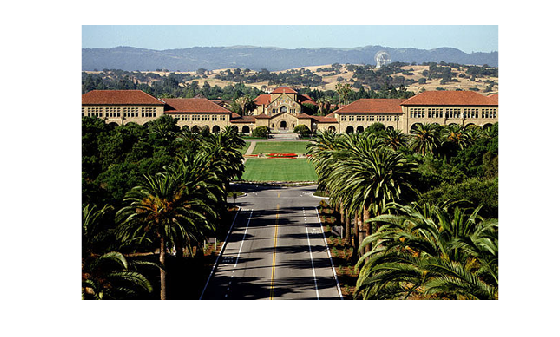

figure; image(A); axis image off

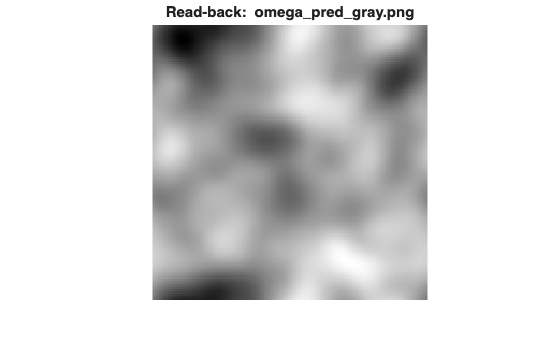

imwrite(A, fullfile(OUT_DIR,'palm.jpeg'), 'jpeg');

% Optional: image I/O on a scientific field (save a vorticity snapshot as an image)
FNO_MAT = fullfile('data','ns2d_fno_pretrained_export.mat');
if ~isfile(FNO_MAT)
    FNO_MAT = 'ns2d_fno_pretrained_export.mat';
end

if isfile(FNO_MAT)
    S = load(FNO_MAT);
    k = 1;
    omegaPred = squeeze(S.omega_pred(k,:,:));

    % Scale to [0,255] for writing (no Image Processing Toolbox needed)
    mn = min(omegaPred(:)); mx = max(omegaPred(:));
    omegaImg = uint8(255 * (omegaPred - mn) / max(mx - mn, eps));

    outPng = fullfile(OUT_DIR,'omega_pred_gray.png');
    imwrite(omegaImg, outPng, 'png');

    B = imread(outPng);
    figure; imagesc(B); axis image off; colormap gray
    title('Read-back: omega\_pred\_gray.png');
end

## Operating System

`clipboard:` Copy/paste strings to/from sys clipboard

`computer:` Information about computer

`dos:` Execute DOS command and return output

`getenv:` Environment variable

`perl:` Call Perl script

`setenv:` Set environment variable

`system:` Execute operating system command and return output

`unix:` Execute UNIX command and return output

`winqueryreg:` Item from Windows registry

`bang (!):` Shell escape System Calls Power of operating system available inside MATLAB

Given stand-alone C/C++/Fortran code with files defining inputs and outputs

- Ability to call executable from within MATLAB

- Use MATLAB's file management to write input files and read output files

- Provides non-intrusive alternative to integrating stand-alone code with MATLAB via MEX interface

`[status,result] = system('command')`

- Calls upon the operating system to execute the given command. The resulting status and standard output are returned.

[status,result] = system('ls')

status = 0

result =     'arrayProduct.cpp
     data
     Lecture_04_a_IO_refactored_with_FNO.mlx
     Lecture_04_b_bigdata.mlx
     Lecture_04_c_pythoncpp.mlx
     outputs
     result_r4_1_19-Dec-2025_10-17-33_385.mat
     simpplot.m
     unsteady.liftdrag.copy
     '
